# Project-2nd file

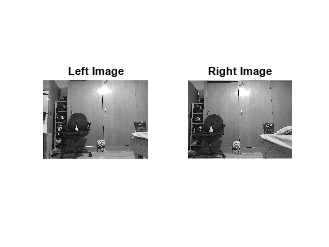

clear,clc,clf,close all;

%load parameters of the cameras:
%load("CameraParamsBen.mat");
load('CamerasData.mat');

%known distances from objects:
% Ben image 1: T=8cm, soda=84cm, coke=115cm
% Ben image 2: T=25cm, whey=111.5cm, scissors=72cm, bamba 167cm,
% candle=235cm
% Ben image 3: T=25cm, protein=110cm, bamba 203cm, whey 170cm
% Ben image 4: T=25cm, bottle=196cm, bamba 213cm, protein 120-125cm
% Bar Image 1: T=42cm, Scotch=76cm
% Bar Image2: T=25cm, Scotch=82cm, Lion=120cm
% Bar Image3: D=25cm, Scotch=82cm, Lion=125cm

%read left image
%Il=imread("Ben1L.jpg");
%Il=rgb2gray(Il);
Il=rgb2gray(CamerasData.CameraBen.Image4.LeftImage);

%read right image
%Ir=imread("Ben1R.jpg");
%Ir=rgb2gray(Ir);
Ir=rgb2gray(CamerasData.CameraBen.Image4.RightImage);

%temp: rotate images because for some reason they are flipped. only Ben1
 %Il=rot90(rot90(Il));
 %Ir=rot90(rot90(Ir));

%units in cm
%distance between the cameras, I measured.
T = CamerasData.CameraBen.Image3.T;

%focal length in pixels from the camera calibration app
%f= cameraParams.Intrinsics.FocalLength(1); %getting the focal length in pixels
f = CamerasData.CameraBen.FocalLength;

%display the images
figure();
subplot(1,2,1);
imshow(Il);
title("Left Image");
subplot(1,2,2);
imshow(Ir);
title("Right Image");

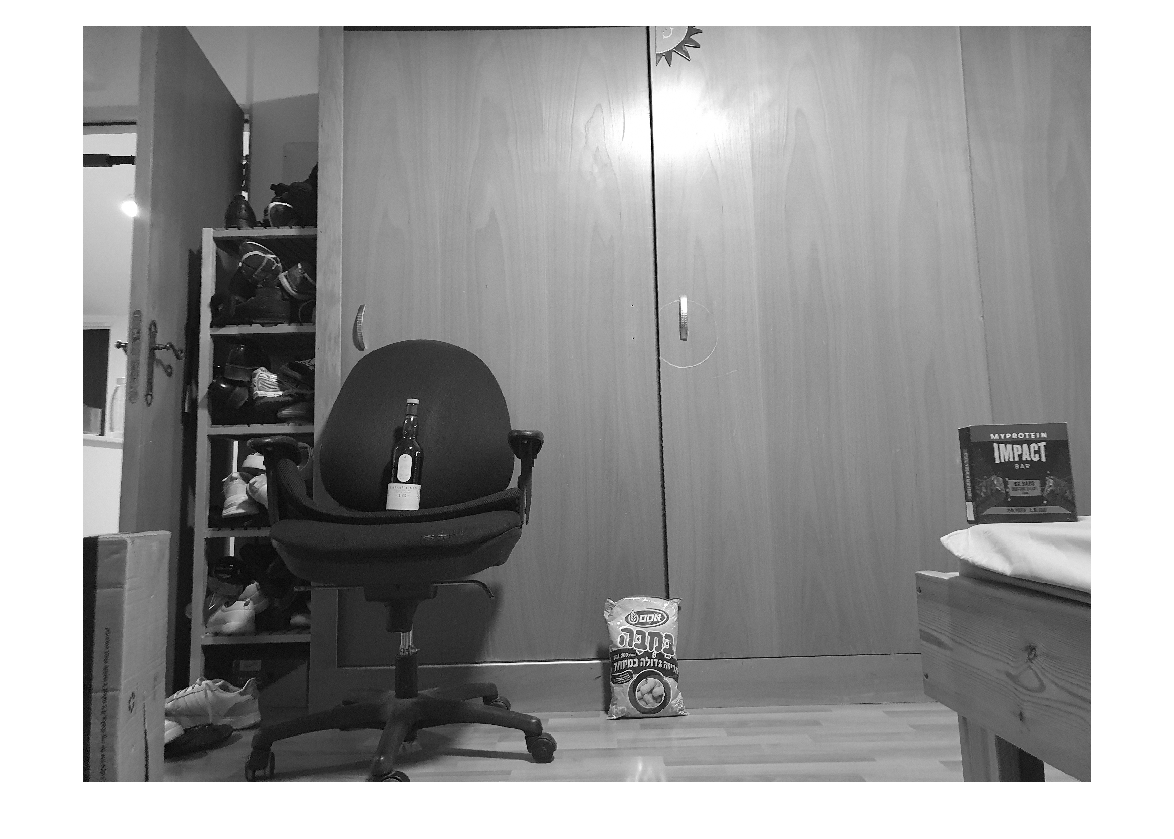


% Display the first image
selectObj = figure();
imshow(Il);
title('Select an object by drawing a rectangle');
rect = getrect; % Get the coordinates of the selected rectangle [x, y, width, height]

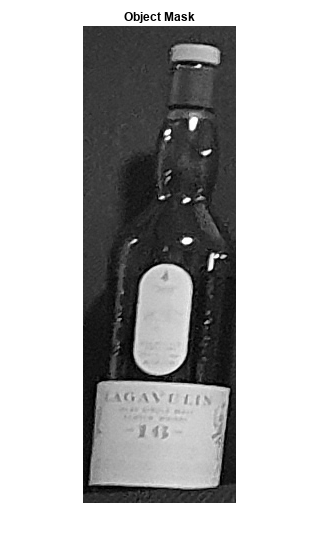


% Extract the object from the first image and display
object_Mask = imcrop(Il, rect);
close (selectObj);
figure();
imshow(object_Mask);
title("Object Mask");

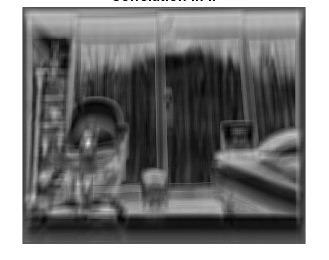


%getting the correlation
corr_objL = normxcorr2(object_Mask,Il);
corr_objR = normxcorr2(object_Mask,Ir);

%showing the corr result
figure();
imshow(corr_objR,[]);
title("Correlation in Ir");


%getting the original objects corrdinates
[original_y1, original_x1] = find(corr_objL == max(max(corr_objL)));

%getting the shifted objects corrdinates
[shifted_y1, shifted_x1] = find(corr_objR == max(max(corr_objR)));

%temp- fix an image
%creating a shifted point
%shifted_point = [shifted_y1 shifted_x1; shifted_y2 shifted_x2];
%original_point= [original_y1 original_x1; original_y2 original_x2];
% getting the transform using the original point and the shifted point
%  tform = fitgeotform2d(shifted_point,original_point,"similarity");
% sameAsInput = affineOutputView(size(Il),tform,"BoundsStyle","SameAsInput");
% %fixing the image
% imwarp(Il,tform,"OutputView",sameAsInput);

%Dispairity calculation.
dispairtyX=original_x1-shifted_x1;
dispairtyY=original_y1-shifted_y1;

%assuming that the dispairity in Y axis is 0.
Z=(f*T)/dispairtyX;

% Display the calculated distance
fprintf('The distance of the object is: %.2f centimeters\n', Z);

The distance of the object is: 200.23 centimeters


## camera struct setup

load("CameraParamsBen.mat");
load("calibrationSession.mat");
%cameras
CamerasData.CameraBar = struct();
CamerasData.CameraBen = struct();
% Set the focal length for CameraBar and CameraBen
CamerasData.CameraBar.FocalLength = calibrationSession.CameraParameters.Intrinsics.FocalLength(1);  % Focal length in millimeters
CamerasData.CameraBen.FocalLength = cameraParams.Intrinsics.FocalLength(1);  % Focal length in millimeters

% Load and assign the images for CameraBar
CamerasData.CameraBar.Image1 = struct('T', 42, 'LeftImage', imread('Bar1L.jpg'), 'RightImage', imread('Bar1R.jpg'),'KnownDistances',"Scotch=76cm");
CamerasData.CameraBar.Image2 = struct('T', 25, 'LeftImage', imread('Bar2L.jpg'), 'RightImage', imread('Bar2R.jpg'),'KnownDistances',"Scotch=82cm\nLion=120cm");
CamerasData.CameraBar.Image3 = struct('T', 25, 'LeftImage', imread('Bar3L.jpg'), 'RightImage', imread('Bar3R.jpg'),'KnownDistances',"Scotch=82cm\nLion=125cm");

% Load and assign the images for CameraBen
CamerasData.CameraBen.Image1 = struct('T', 8, 'LeftImage', imread('Ben1L.jpg'), 'RightImage', imread('Ben1R.jpg'),'KnownDistances',"Soda=84cm\nCoke=115cm");
CamerasData.CameraBen.Image2 = struct('T', 25, 'LeftImage', imread('Ben2L.jpg'), 'RightImage', imread('Ben2R.jpg'),'KnownDistances',"Whey=111.5cm\nScissors=115cm\nBamba=167cm\nCandle=235cm");
CamerasData.CameraBen.Image3 = struct('T', 25, 'LeftImage', imread('Ben3L.jpg'), 'RightImage', imread('Ben3R.jpg'),'KnownDistances',"Protein bars=110cm\nBamba=203cm\nWhey=170cm");
CamerasData.CameraBen.Image4 = struct('T', 25, 'LeftImage', imread('Ben4L.jpg'), 'RightImage', imread('Ben4R.jpg'),'KnownDistances',"Scotch=196cm\nBamba 213cm\nProtein=120-125cm");

## test

clear,clc,clf;
load('CamerasData.mat');
z=DistanceCalc(CamerasData.CameraBen.Image4.LeftImage,CamerasData.CameraBen.Image4.RightImage,CamerasData.CameraBen.FocalLength,CamerasData.CameraBen.Image4.T)

z = 209.9484